
% set parameters
S_0 = 100;
r = 0.05;
T = 1;
H=103;
L=98;
% number of discretization points of the interval [0,T]
N = 100;
dt = T/N;
t = dt:dt:T;
%Sensitivity analysis
Q=zeros(10,1);
for i=1:1:10
    Q(i)=FC_Boosterprice(S_0, L, H, t, r, dt, i/20);
    
end
disp(Q);

    0.4915
    0.3112
    0.2207
    0.1697
    0.1374
    0.1152
    0.0991
    0.0868
    0.0772
    0.0694



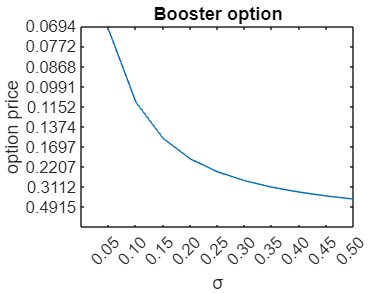

plot(Q)
xticklabels({'0.05', '0.10', '0.15' '0.20', '0.25','0.30','0.35','0.40','0.45','0.50'});
yticklabels({'0.4915', '0.3112', '0.2207' '0.1697', '0.1374','0.1152','0.0991','0.0868','0.0772','0.0694'});
xlabel('σ');
ylabel('option price');
title('Booster option');

function P = FC_Boosterprice(S_0, L, H, t, r, dt, sigma)
d1 = (log(S_0/L)+(r-sigma^2/2)*t)./(sigma*sqrt(t));
d2 = (log(S_0/H)+(r-sigma^2/2)*t)./(sigma*sqrt(t));
P = exp(-r*t(end))*(sum((normcdf(-d2)-normcdf(-d1))*dt));
end
